# A Service Queue with Impatient Customers

## Problem

Consider a queue to which customers arrive according to a [Poisson process](https://en.wikipedia.org/wiki/Poisson_point_process) with rate λ per hour. Suppose that the queue has a single server. Each customer who arrives at the queue counts the length r of the queue and decides to leave with probability $p_{r}=\begin{cases}
1-1/r & \text{ if } r=1,2,... \\ 
0 & \text{ if } r=0 
\end{cases}$. A customer who leaves does not enter the queue again. Each customer who enters the queue waits in the order of arrival until the customer immediately in front is done being served, and then moves to the head of the queue. The time (in hours) to serve a customer, after reaching the head of the queue, is an [exponential random variable](https://en.wikipedia.org/wiki/Exponential_distribution) with parameter μ. Assume that all service times are independent of each other and of all arrival times.

Estimate the expected number of customers in the queue at a particular time t after the queue opens for business. Suppose that λ = 2, μ = 1, t = 3.

## Solution by L.Z.

1. Interarrival times X1, X2, ... of the Poisson process are i.i.d. exponential random variables with parameter $\lambda$. Let $T_j$ be the time at which customer j arrives, then $T_{j}=\sum_{i}^{j}X_{i}$. Stop simulating at the first k such that $T_k>t$. Only the first k − 1 customers have even arrived at the queue by time t. 

2. For each customer j = 1,...,k − 1, simulate a service time $Y_j$ having the exponential distribution with parameter μ. Let $Z_j$ stand for the time at which the jth customer reaches the head of the queue, and let $W_j$ stand for the time at which the jth customer leaves the queue.

3. The jth customer counts the length of the queue on arrival and decides to leave with probability $p_r$. Let $U_{i,j}$ be an indicator such that $U_{i,j}=1$ if customer i is still in the queue when customer j arrives (i < j), and $U_{i,j}=0$ if customer i has already left the queue. 


$$U_{i,j}=\begin{cases}
1 & \text{ if }  W_{i}>=T_{j}\\ 
0 & \text{ if }  W_{i}<T_{j}
\end{cases}$$


Then, the number of customers in the queue when the jth customer arrives is  $r=\sum_{i=1}^{j-1}U_{i,j}$ 

4. We then simulate a random variable $V_j$ having the Bernoulli distribution with parameter $p_r$. If $V_{j}=1$, customer j leaves the queue immediately so that $W_j=T_j$.  If customer j stays in the queue, then this customer reaches the head of the queue at time $Z_{j}=max\left \{T_{j},W_{1}, ..., W_{j-1} \right \}$. That is, the jth customer either reaches the head of the queue immediately upon arrival (if nobody is still being served) or as soon as all of the previous j − 1 customers have left, whichever comes later. Also, $W_{j}=Z_{j}+Y_{j}$ if customer j stays. For each j = 1,...,k − 1, the jth customer is in the queue at time t if and only if $W_{j}\geq t$.

% parameters initialization
lambda=2;mu=1;t=3;
%  generating inter-arriving times Xi
j=round(t/(1/lambda));
X=exprnd(1/lambda,[1,j]);
while sum(X)<=t
    j=j+1;
    X(j)=exprnd(1/lambda);
end
while sum(X)>t
    X(j)=[];
    j=j-1;
end
% service times for j customers who arrived in t hours 
Y=exprnd(1/mu,[1,j]);
T=zeros(1,j);Z=zeros(1,j);W=zeros(1,j+1);% a trick used here: let W(1) stands for W(0),...
% thus the i-th customer leaves at W(i+1)
W(1)=0;
for i=1:j % for the i-th customer
    T(i)=sum(X(1:i)); %the arriving time of the i-th customer
    r=nnz(W(1:i)>T(i));% # of people in front of the i-th customer ...
    %when he arrives
    if r==0
        pr=0;
    else 
        pr=(1-1/r);
    end
    if binornd(1,pr)==1 %if the i-th customer leaves immediately
        W(i+1)=T(i); %leaving time      
    else %if the i-th customer stays in line
        Z(i)=max([T(i),W(1:i)]); % he reaches the head of the line at Z(i)
        W(i+1)=Y(i)+Z(i);
    end
end
n=nnz(W>t)

n = 3

Save the above script as a function simulate(lambda,mu,t) and simulate until simulation error is small

nboot=0;increment=100;improvement =1;error=10^16; bootstat=[];
number_of_sims=100;goal=0.1; %precision goal.
tic
while abs(improvement)>10/100 || error/goal>1  %stop when sample variance is stable ...
    %and precision goal is reahced.
    if abs(improvement)>10/100
        nboot=nboot+increment;        
        bootstat=[bootstat,zeros(1,increment)];
        parfor j=nboot+1-increment:nboot
            n=zeros(1,number_of_sims);
            for i=1:number_of_sims
                n(i)=simulate(2,1,3);% for the case that lambda=2,mu=1,t=3
            end
            bootstat(j)=mean(n);
        end
    end
    improvement=(error-var(bootstat))/error;
    error=var(bootstat)%error is defined as sample variance
    nboot
    if error/goal>1
        number_of_sims=round(error/goal*number_of_sims)
    end
end

error = 0.0180

nboot = 100

number_of_sims = 180

error = 0.0141

nboot = 200

number_of_sims = 255

error = 0.0114

nboot = 300

number_of_sims = 291

error = 0.0099

nboot = 400

error = 0.0092

nboot = 500

toc

时间已过 8.433376 秒。


mean(bootstat)

ans = 2.1840

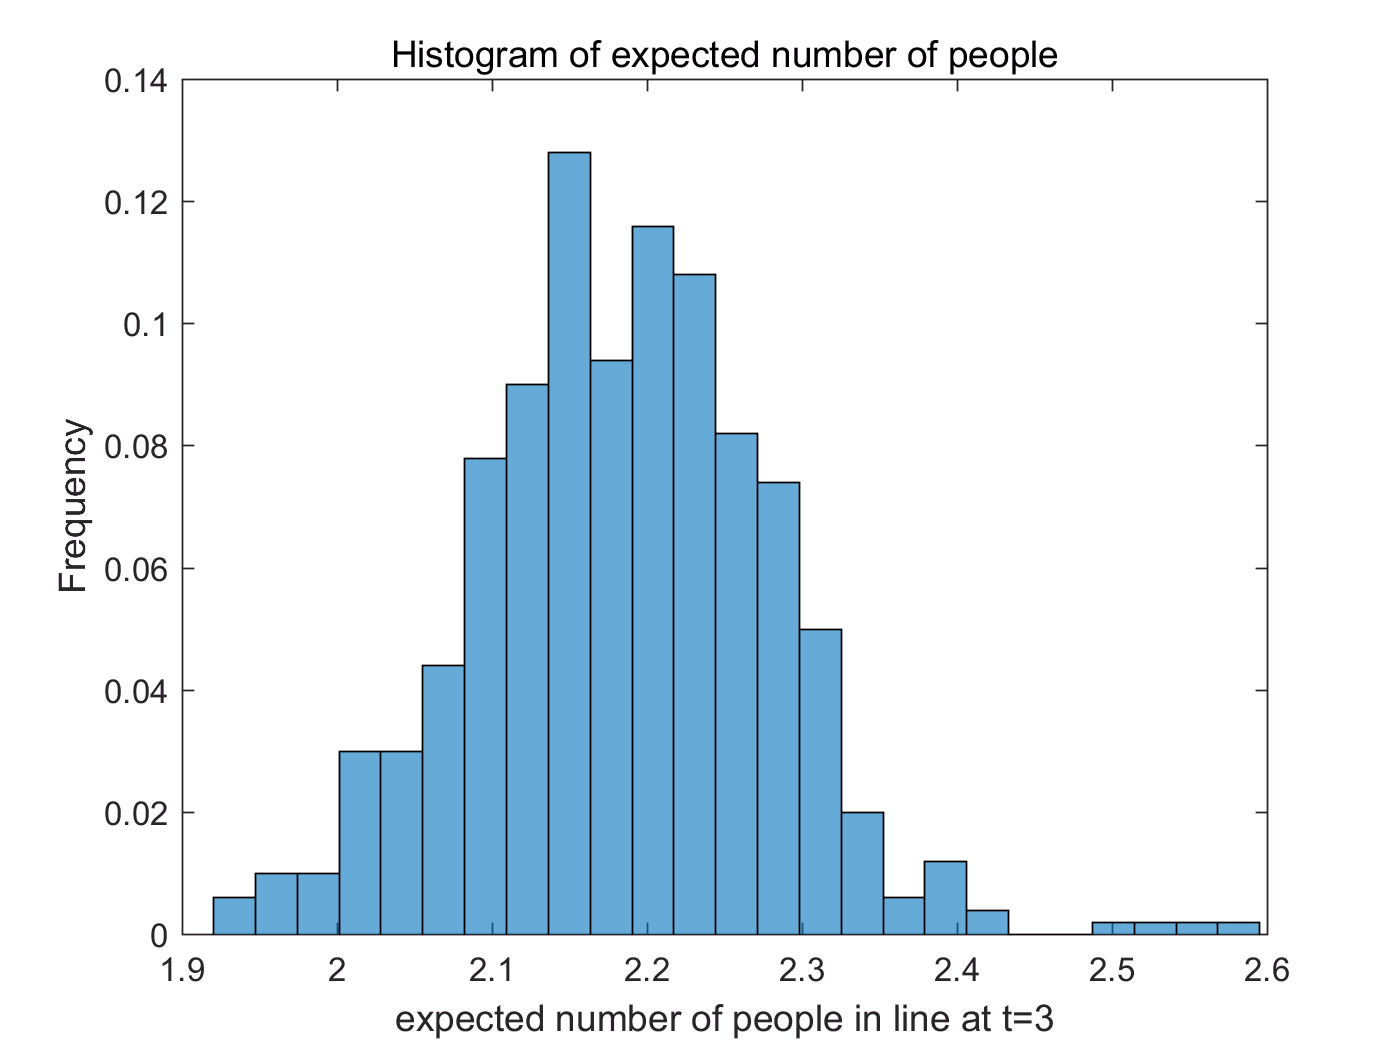

h=histogram(bootstat,'Normalization','probability');
h.NumBins=25;
title('Histogram of expected number of people');
xlabel(strcat('expected number of people in line at t=',num2str(t)));ylabel('Frequency');

95% confidence Interval for expected number of people in line at the specified timestamp:

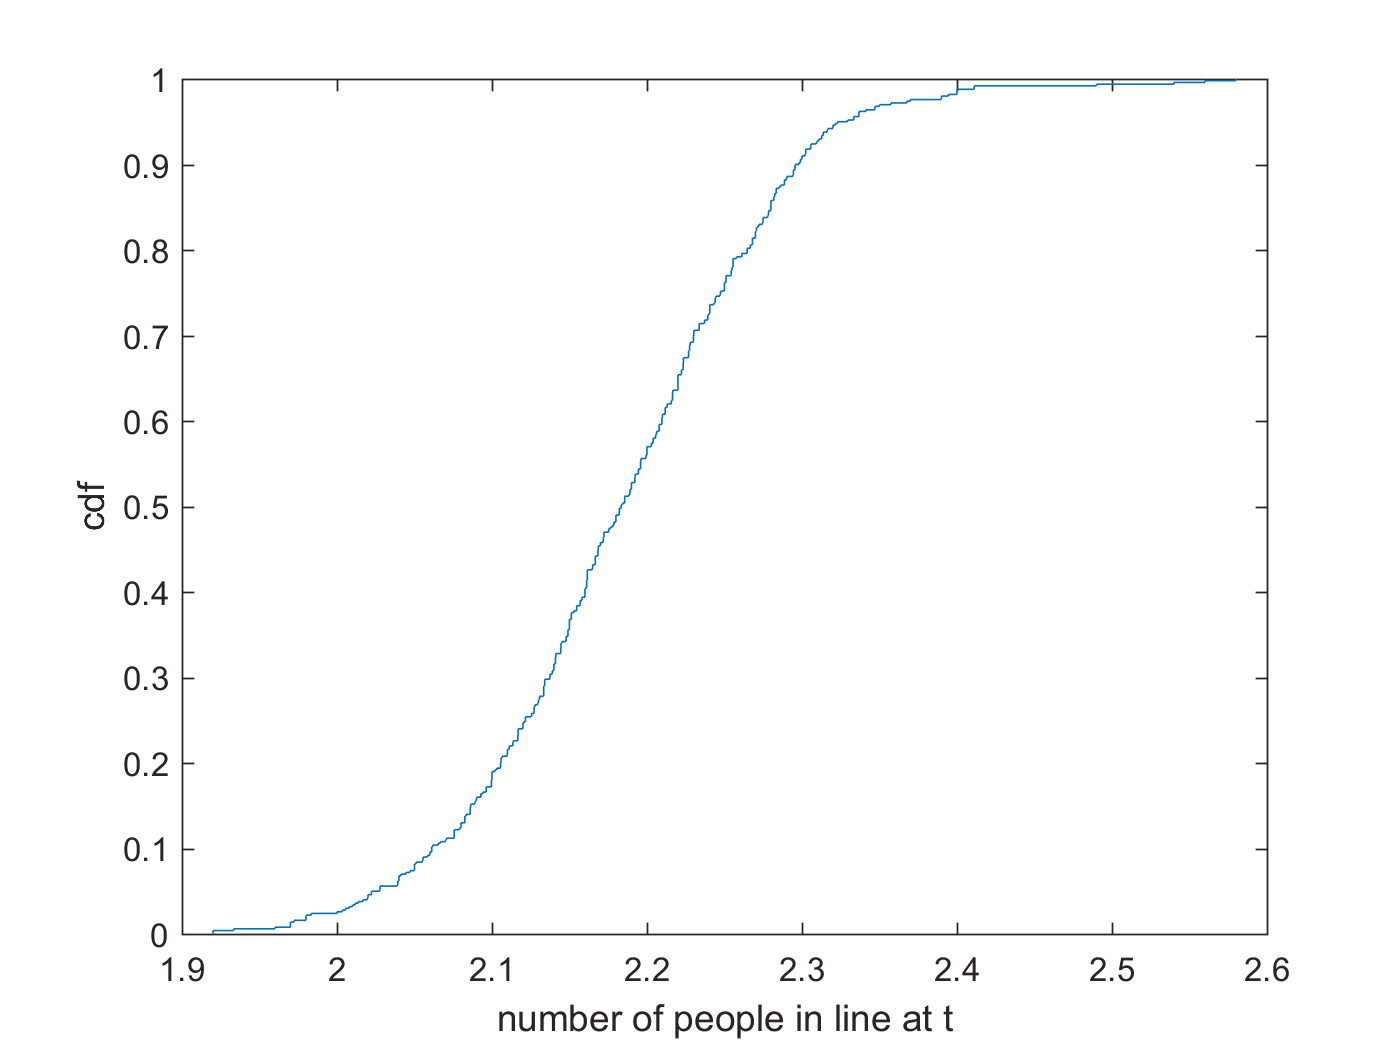

ecdf(bootstat);xlabel('number of people in line at t');ylabel('cdf');

obj=paretotails(bootstat,0.1,0.9);
disp(strcat('95% Confidence Interval is:   ',...
    ' [',num2str(icdf(obj,0.025)),',',num2str(icdf(obj,0.975)),']'))

95% Confidence Interval is: [1.9981,2.3644]
